# Coursework 2 - Completed by Yousef Abdalla (14296919)

Please submit all question regarding this coursework in the Coursework 2 section forum in Q&A part in the Moodle page. ***No**** code should be submitted or discussed in the Forum.*

**Marks:** 30% of module mark. Marking rubric is on Moodle. Marks and feedback will be provided 15 working days after the submission deadline dependent on Extenuating Circumstances applications and academic misconduct panel; each student will receive an individual copy of the marking rubric posted on Moodle by email. If required, further individual feedback is then available by requesting a one-to-one meeting.

**Submission **via Moodle as a zipped file**: **

- MATLAB live script (.mlx) and 

- its PDF export

**Deadline: **Wednesday 6 May 2021 at 3pm.

**Supplied files: **For Question 4, you will need the accompanying dataset in the zipped-folder "handwritten_number_rgb". 

**Note about copying code: **We may use MOSS ([http://theory.stanford.edu/~aiken/moss/](http://theory.stanford.edu/~aiken/moss/)) to check for similarity between pieces of code - both with other students and with code available online.  Please WRITE YOUR OWN CODE and do not just copy from online examples - you will get zero if you are found doing this.

### Instructions:

- All answers must be written in this file.

- For your coursework submission, you will **submit this mlx file **and** the PDF** which contains the questions and the answers (descriptive answer and codes). 

- Local functions should be written at the end of the mlx files 

- In addition to the code to produce results and plots, **any plot must be embedded within the mlx file as image**. It can be done by insert > image. 

- This mlx must be self-contained. That is, **this script will run with "no change", except for a line in question 4 in which it will be modified by me to refer to my own testing directory.** 

**IMPORTANT: **Once you have completed the coursework you *MUST* export it to a PDF document. These options can be found under the 'Save' button:

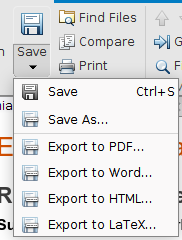

Put your completed .mlx file and the PDF exported version, in a single zip file and upload to Moodle. I will usually mark the PDF export but may choose to run your .mlx file

### Matlab requisite:

- Matlab Image-Processing Toolbox for Question 4

## Question 1 - Dichotomy of 2-Dimensional Boolean Operator XNOR  [20%]

### Task 1(a) 

Complete the truth table of 2-dimensional Boolean Operator XNOR, below. 

**__________________________________**

   $a_1 $        **|**         $a_2$          **|**         XNOR       **|**     

**__________________________________**

      0                  0                         1

      0                  1                         0

      1                  0                         0

      1                  1                         1

**___________________________________**

### Task 1(b) 

Draw with annotation the mapping of the XNOR operator from input to the output space.

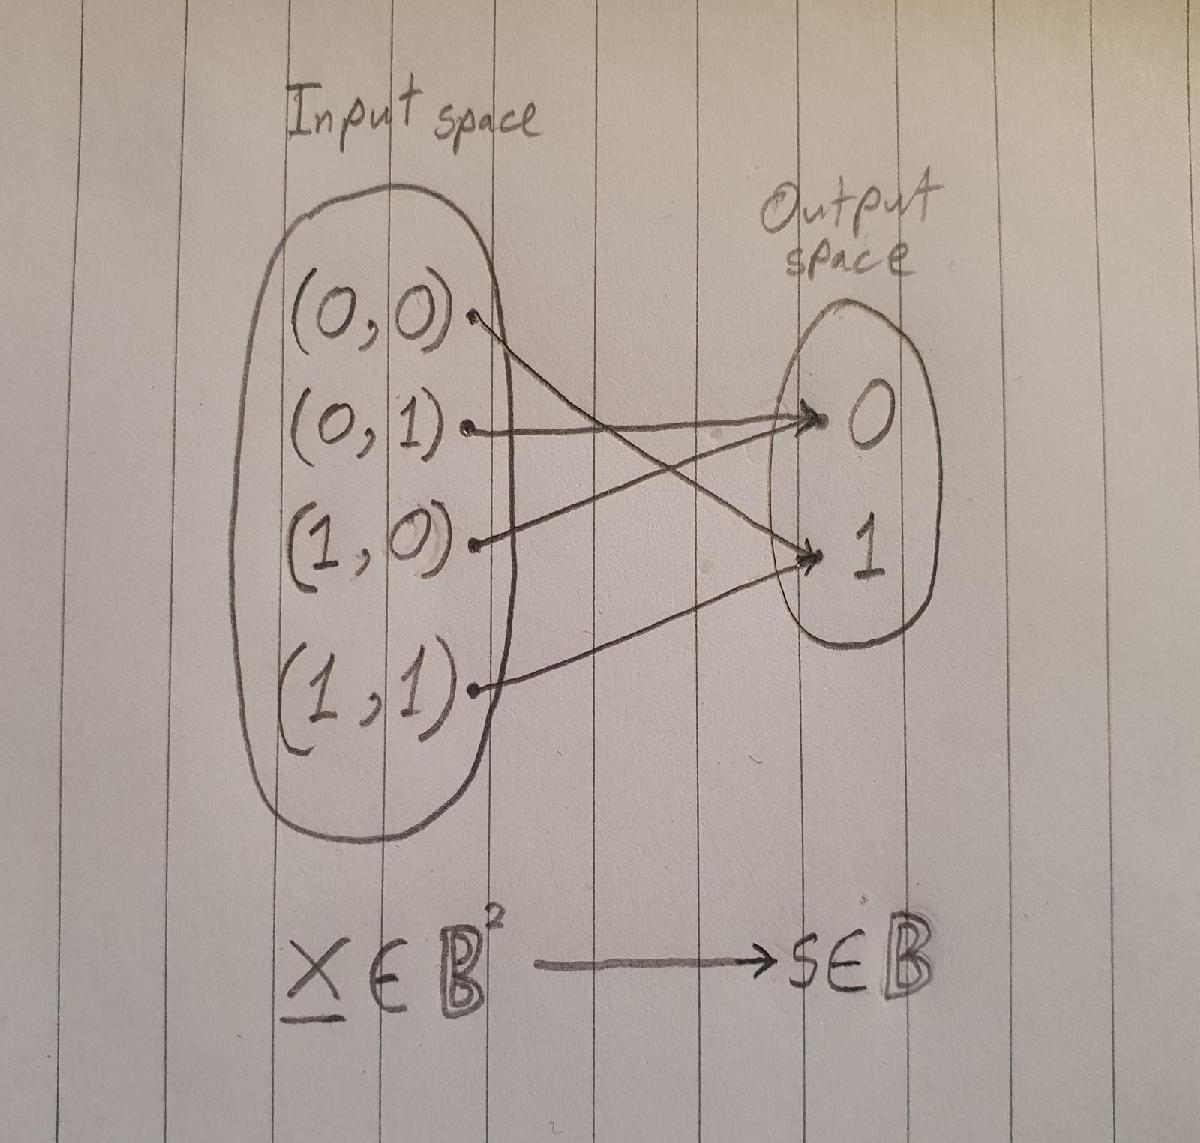

### Task 1(c) 

Is XNOR a linearly separable or a non-separable problem? 

    *- XNOR is not a linearly separable Boolean function. The evidence supporting this can be seen by plotting the **2D cube** of the function where a solid circle indicates output of 1 and hollow circle indicates the output of 0.*

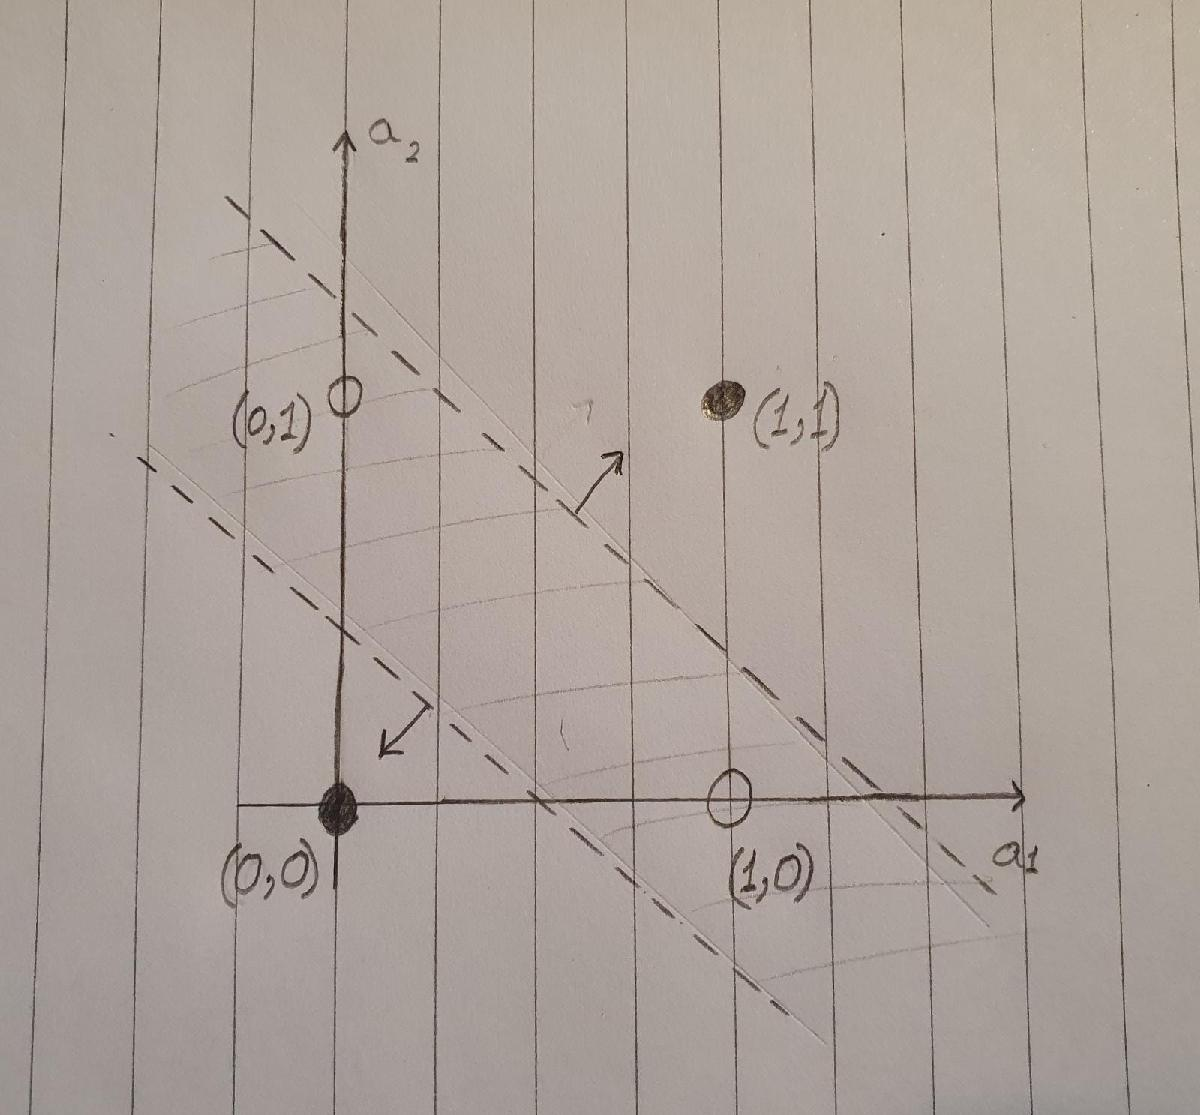

    - *It can be seen that a single line cannot separate the two output classes {0,1}, which is the feature of a linearly separable function. Therefore, as shown in the figure above, two linear lines must be used to separate them. (Due to the limitation imposed by the capacity of a single threshold logic neuron).*

### Task 1(d) 

Sketch with detailed annotation and describe a Threshold Logic Neuron Network architecture which can evaluate the XNOR operation. 

*    - Through analysing both linear lines seperating the XNOR boolean function, and using critical thinking, one can reach the conclusion that an XNOR boolean function can be expressed using the following general equation. (Written both in plain english and as an algebraic expression)*

*Input1 XNOR Input2 = (Input1 AND Input2) OR (Input1 NOR Input2).*

    
$$p\odot q=\left(p\;\ldotp \;q\right)\;+\;\bar{\left(p+q\right)}$$


    *-* *As such, the XNOR operation can be achieved using the following Threshold Logic Neuron Network shown below which is a 2 layer Neural Network (Input, Hidden, Output).*

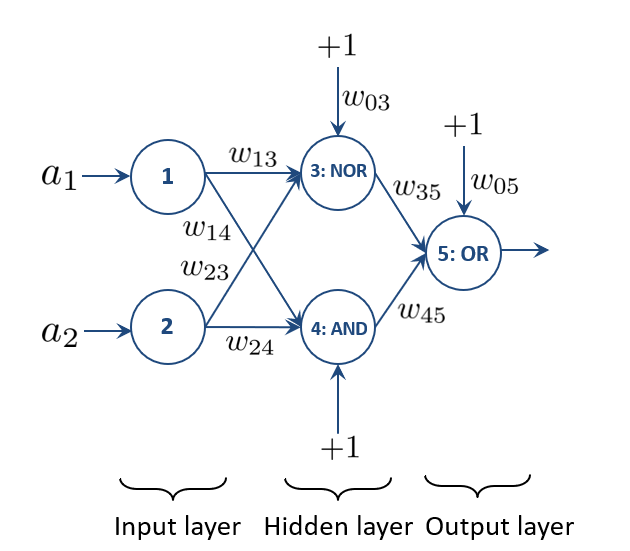

### Task 1(e) 

Find the weight and bias of the Threshold Logic Neuron network architecture in Task 1(d). 

- **0 < Bias <= 2**

        
$$\underline{\underline{W}}_{ih}= 
\pmatrix{-1, 1 \cr
-1, 1\cr
-1, 1
}$$


        
$$\underline{\underline{W}}_{hj} = 
\pmatrix{ -1 \cr
1 \cr
1
}$$


  where $\underline{\underline{W}}_{ih}$ is the weight of between the input and hidden layer and $\underline{\underline{W}}_{hj}$ is the weight of between the hidden and output layer.

### Task 1(f) 

Based on the weights obtained in Task 1(e), draw the separating hyperplane in the input pattern space. (Please provide detailed annotations) 

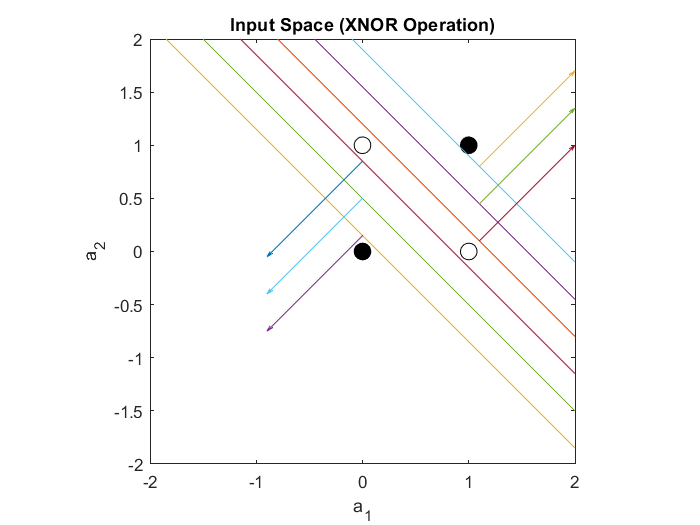

clear; clc;

% Input set
A = [ 0 0 1 1;...    %a_1
    0 1 0 1; ];      %a_2

% Desired output, i.e. Teaching set
D = [ 1 0 0 1 ];

% weight matrix of from input to hidden layer
W_i_h = [ -1 1 ;...    % first column is the weight of NOR gate
    -1 1 ;...          % second column is the weight of AND gate
    -1 1];

% weight matrix of from hidden to output layer
W_h_o = [-1;...   % first row is the bias weight
    1;...           % first column is the weight of OR gate
    1];

% Plot the input parameter space
figure;
plot(A(1,:),A(2,:),'LineStyle','none','Marker','o','MarkerSize',10,'MarkerEdgeColor', ...
    'k', 'MarkerFaceColor','w');
hold on;
plot(A([1,1 4]),A([2,1 4]),'LineStyle','none','Marker','o','MarkerSize',10, ...
    'MarkerEdgeColor','k','MarkerFaceColor','k');

% insert labels, title and axis/range options
xlabel('a_1');
ylabel('a_2');
title('Input parameter space');
axis equal;
xlim([-2,2]);ylim([-2,2]);

% Isolate first signal inputs for use as function parameter
a_1 = A(1,:);

% an inline function for discimination function
disc_func =@(W_i_h,a_1) -(W_i_h(2)/W_i_h(3))*a_1 - (W_i_h(1)/W_i_h(3));

% working variable
aa1 = [-2,2];

% try different bias values to determine acceptable range
for bias = 0.15:0.35:2
    
    W_i_h(1) = bias; % modify the bias weight
    
    % plot seperation hyperplane
    plot(aa1,[disc_func(W_i_h,aa1(1));disc_func(W_i_h,aa1(2))]); 
    hold on;
    
    % plot arrows pointing towards positive/correct output
    if bias < 1
        drawArrow([1 1+W_i_h(2)]-1,[disc_func(W_i_h,1);disc_func(W_i_h,1)+W_i_h(3)]+1, ...
            'linewidth',1.2);
    else
        drawArrow(-[1 1+W_i_h(2)]+2.1,-[disc_func(W_i_h,1); ...
            disc_func(W_i_h,1)+W_i_h(3)]+1, 'linewidth',1.2);
    end
    
end

% add axis and range options
axis equal
title("Input Space (XNOR Operation)")
xlim([-2,2]);ylim([-2,2]);
hold off
hold off

### Task 1(g) 

Now, use the Back-Propagation algorithm for a single hidden layer ANN with sigmoid activation function, find the weights and bias of the ANN which can perform this operation. 

[*You ****must**** use the sigmoid back-propagation (BP) blackbox function provided at the end of this file, to perform this Task. ****Use of Matlab ANN toolbox, for example ***`patternnet, trainNetwork, feedforwardnet `***and others is not permitted.***]  

[Use parameter number of hidden neuron = 2, $\eta=0.2$, $\alpha = 0.5$ and $tol=1\times10^{-4}$]

clear; clc;
rng(1); % DO NOT MODIFY THIS LINE


% Input set
A = [ 0 0 1 1;...    %a_1
    0 1 0 1; ];      %a_2

% Desired output, i.e. Teaching set
D = [ 1 0 0 1 ];

% Weight matrix from input to hidden layer
Wih_guess = rand(3,2);

% Weight matrix of from hidden to output layer
Whj_guess = ones(3,1);

% Function parameters
lambda = 1 ;
eta = 0.2;
alpha = 0.5;
tol = 1*10^-4;
num_hidden_neuron = 2;

% Backpropagation sigmoid function
[Wih,Whj] = backpropagation_1hiddenLayer_blackbox(A,...
    D,...
    lambda,...
    eta,...
    alpha,...
    tol,...
    num_hidden_neuron,...
    Wih_guess,...
    Whj_guess)

Epoch : 10000 | MSE : 7.726e-04 
Epoch : 20000 | MSE : 2.777e-04 
Epoch : 30000 | MSE : 1.673e-04 
Epoch : 40000 | MSE : 1.192e-04 


Wih =     7.6823    2.8173
   -5.1457   -6.7237
   -5.1575   -6.7840


Whj =     5.1725
  -10.8272
   10.9567



$$\underline{\underline{W}}_{ih}= 
\pmatrix{  7.6823, 2.8173 \cr
-5.1457, -6.7237 \cr
-5.1575, -6.7840}$$



$$\underline{\underline{W}}_{hj} = 
\pmatrix{ 5.1725 \cr
-10.8272 \cr
10.9567
}$$


where $\underline{\underline{W}}_{ih}$ is the weight of between the input and hidden layer and $\underline{\underline{W}}_{hj}$ is the weight of between the hidden and output layer.

The MSE based on the calculated $\underline{\underline{W}}_{ih}$ and $\underline{\underline{W}}_{hj}$,


$$MSE = 1.192e-04$$


### **Task 1(h)**

List and describe the differences between the classification done in Task 1(d,e,f) and Task 1(g).

*    - As illustrated in Task(f), several different hyperplanes can be used to perform this classification, however at the initial stage of constructing a Threshold Logic Neuron Network, the weights of the signals interconnecting the neurons can only be guessed. The best to do this is to either give them and initial value of one, or to set them to random small numbers between 1 and -1. In any case, the initial weights are then modified using the Back Propagation Method to teach the algorithm to better perform the classification. After completing the training of the algorithm, the new modified weights are produced, along with the Mean Squared Error (MSE). It can be seen that as the training iterations pass (Epoch), the algorithm learns, and it's chances in making an erroneous classification decreases, until it drops under the tolerance specified by the user, fInally producing new modified weight values that can perform an accurate classification.*

## Question 2 - Artificial Neural Network Application for Iris Flower Classification [25%]

For this Question, you will need the Iris flower dataset. 

clear; clc;

[A,D] = iris_dataset; % Matlab has Iris flower dataset


### Task 2(a) 

What is the dimensionality of the input and the output for the classification of the Iris flower dataset? 

    *- The input A is a 2-dimensional matrix with 4 rows & 150 columns. *

*        - The dimensionality of the input is 12, as there are 4 features which produce 6 combinations, each of which has 2 permutations. *

*    - The output D is a 2-dimensional matrix with 3 rows & 150 columns.*

*        - The dimensionality of the output is 3, as there are 3 distinctive species that can be used for classifying the flowers. (Setosa, Versicolor, Virginica)*

### Task 2(b) 

Draw the 2-dimensional convex hulls of the Iris flowers species, considering all the input parameter space. 

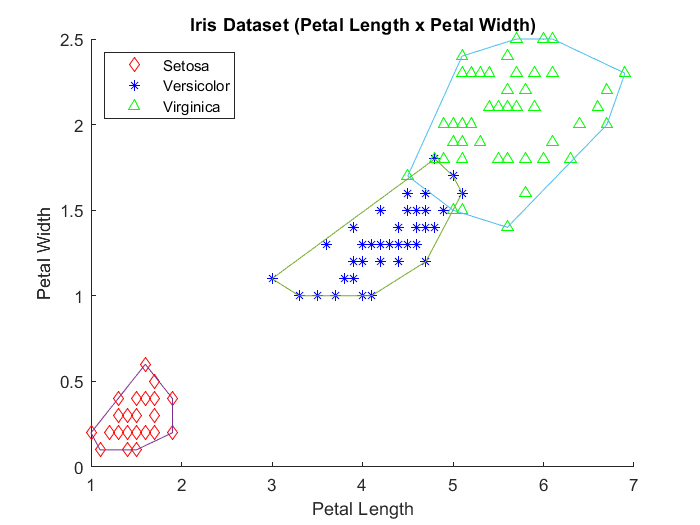

clear; 
clc;

% Matlab has Iris flower dataset
[IrisInputs,IrisTargets] = iris_dataset; 

% Seperate species
Species1 = IrisInputs(:,1:50);
Species2 = IrisInputs(:,51:100);
Species3 = IrisInputs(:,101:150);

%%%%%%%%%%%%%%%%%%%%%%%%% Combination PetalLength x PetalWidth %%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Permutation 1 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

scatter(Species1(3,:), Species1(4,:),'rd'); xlabel('Petal Length') ;ylabel('Petal Width'); 
hold on;
scatter(Species2(3,:), Species2(4,:),'b*');
scatter(Species3(3,:), Species3(4,:),'g^');

% Plot convex hulls around unique specie classes
[k,~] = convhull(Species1(3,:), Species1(4,:));
plot(Species1(3,k),Species1(4,k));

[k2,~] = convhull(Species2(3,:), Species2(4,:));
plot(Species2(3,k2),Species2(4,k2));

[k3,~] = convhull(Species3(3,:), Species3(4,:));
plot(Species3(3,k3),Species3(4,k3));

title('Iris Dataset (Petal Length x Petal Width)')
legend('Setosa','Versicolor','Virginica','Location',"northwest")
hold off

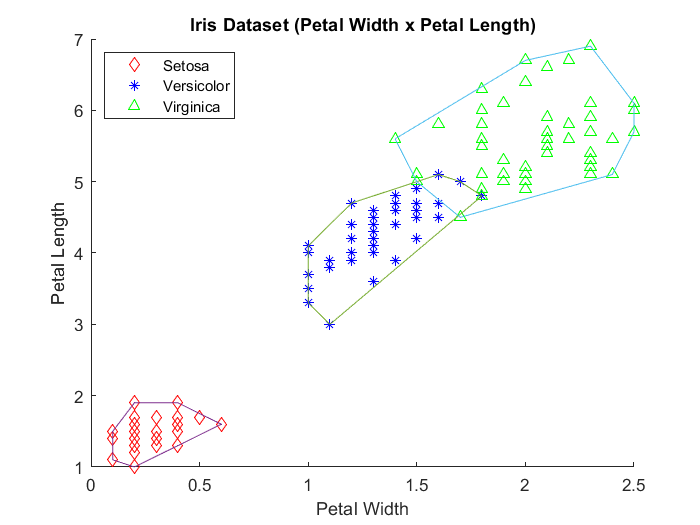

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Permutation 2 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

scatter(Species1(4,:), Species1(3,:),'rd'); xlabel('Petal Width') ;ylabel('Petal Length'); 
hold on;
scatter(Species2(4,:), Species2(3,:),'b*');
scatter(Species3(4,:), Species3(3,:),'g^');

% Plot convex hulls around unique specie classes
[k,~] = convhull(Species1(4,:), Species1(3,:));
plot(Species1(4,k),Species1(3,k));

[k,~] = convhull(Species2(4,:), Species2(3,:));
plot(Species2(4,k),Species2(3,k));

[k,~] = convhull(Species3(4,:), Species3(3,:));
plot(Species3(4,k),Species3(3,k));

title('Iris Dataset (Petal Width x Petal Length)')
legend('Setosa','Versicolor','Virginica','Location',"northwest")
hold off

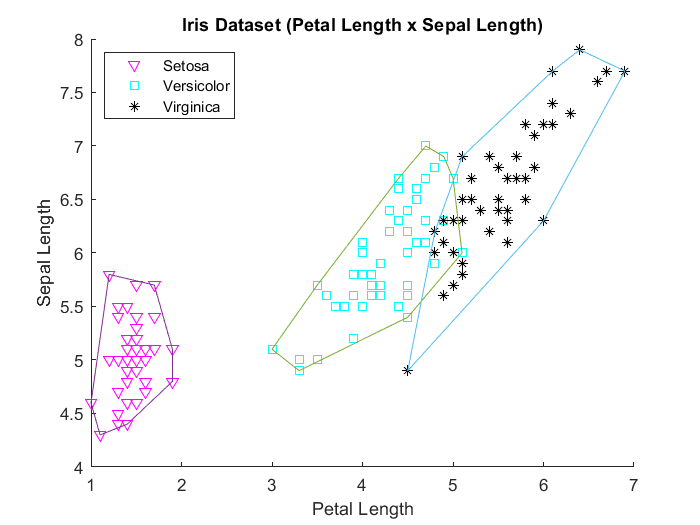

%%%%%%%%%%%%%%%%%%%%%%% Combination PetalLength x SepalLength %%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Permutation 1 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

scatter(Species1(3,:), Species1(1,:),'mv'); xlabel('Petal Length') ;ylabel('Sepal Length'); 
hold on;
scatter(Species2(3,:), Species2(1,:),'cs');
scatter(Species3(3,:), Species3(1,:),'k*');

% Plot convex hulls around unique specie classes
[k,~] = convhull(Species1(3,:), Species1(1,:));
plot(Species1(3,k),Species1(1,k));

[k,~] = convhull(Species2(3,:), Species2(1,:));
plot(Species2(3,k),Species2(1,k));

[k,~] = convhull(Species3(3,:), Species3(1,:));
plot(Species3(3,k),Species3(1,k));

title('Iris Dataset (Petal Length x Sepal Length)')
legend('Setosa','Versicolor','Virginica','Location',"northwest")
hold off

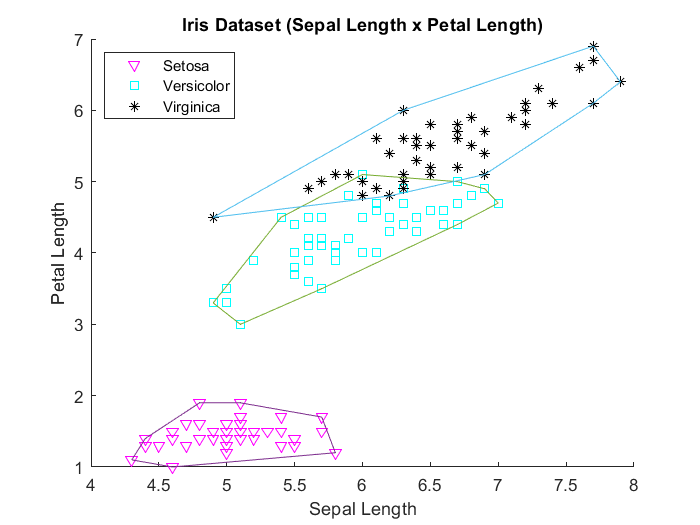

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Permutation 2 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

scatter(Species1(1,:), Species1(3,:),'mv'); xlabel('Sepal Length') ;ylabel('Petal Length'); 
hold on;
scatter(Species2(1,:), Species2(3,:),'cs');
scatter(Species3(1,:), Species3(3,:),'k*');

% Plot convex hulls around unique specie classes
[k,~] = convhull(Species1(1,:), Species1(3,:));
plot(Species1(1,k),Species1(3,k));

[k,~] = convhull(Species2(1,:), Species2(3,:));
plot(Species2(1,k),Species2(3,k));

[k,~] = convhull(Species3(1,:), Species3(3,:));
plot(Species3(1,k),Species3(3,k));

title('Iris Dataset (Sepal Length x Petal Length)')
legend('Setosa','Versicolor','Virginica','Location',"northwest")
hold off

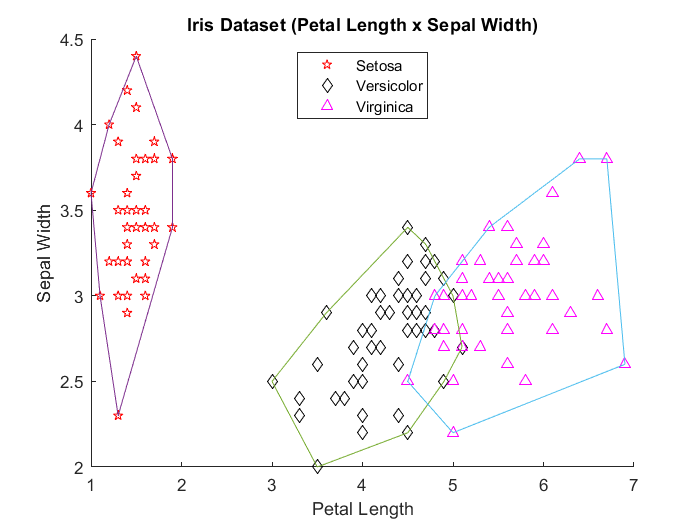

%%%%%%%%%%%%%%%%%%%%%%%%%% Combination PetalLength x SepalWidth %%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Permutation 1 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

scatter(Species1(3,:), Species1(2,:),'rp'); xlabel('Petal Length') ;ylabel('Sepal Width'); 
hold on;
scatter(Species2(3,:), Species2(2,:),'kd');
scatter(Species3(3,:), Species3(2,:),'m^');

% Plot convex hulls around unique specie classes
[k,~] = convhull(Species1(3,:), Species1(2,:));
plot(Species1(3,k),Species1(2,k));

[k,~] = convhull(Species2(3,:), Species2(2,:));
plot(Species2(3,k),Species2(2,k));

[k,~] = convhull(Species3(3,:), Species3(2,:));
plot(Species3(3,k),Species3(2,k));

title('Iris Dataset (Petal Length x Sepal Width)')
legend('Setosa','Versicolor','Virginica','Location',"north")
hold off

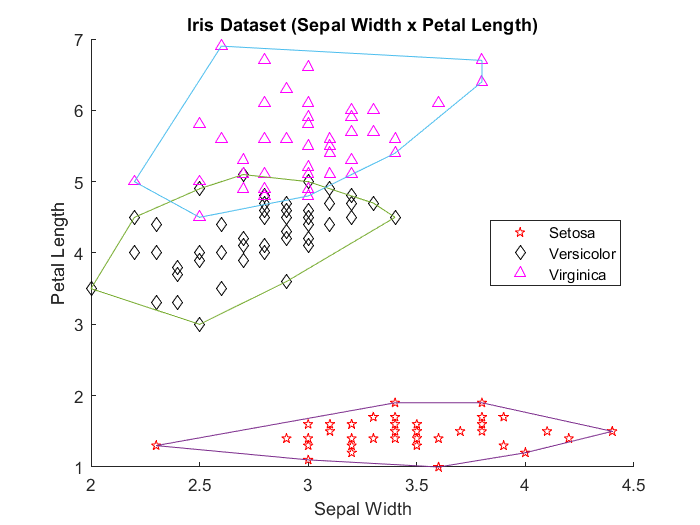

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Permutation 2 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

scatter(Species1(2,:), Species1(3,:),'rp'); xlabel('Sepal Width') ;ylabel('Petal Length'); 
hold on;
scatter(Species2(2,:), Species2(3,:),'kd');
scatter(Species3(2,:), Species3(3,:),'m^');

% Plot convex hulls around unique specie classes
[k,~] = convhull(Species1(2,:), Species1(3,:));
plot(Species1(2,k),Species1(3,k));

[k,~] = convhull(Species2(2,:), Species2(3,:));
plot(Species2(2,k),Species2(3,k));

[k,~] = convhull(Species3(2,:), Species3(3,:));
plot(Species3(2,k),Species3(3,k));

title('Iris Dataset (Sepal Width x Petal Length)')
legend('Setosa','Versicolor','Virginica','Location',"east")
hold off

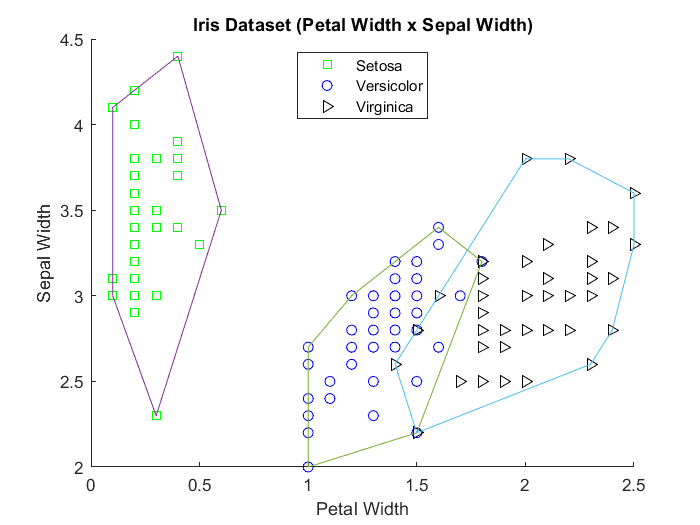

%%%%%%%%%%%%%%%%%%%%%%%%%%% Combination PetalWidth x SepalWidth %%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Permutation 1 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

scatter(Species1(4,:), Species1(2,:),'gs'); xlabel('Petal Width') ;ylabel('Sepal Width'); 
hold on;
scatter(Species2(4,:), Species2(2,:),'bo');
scatter(Species3(4,:), Species3(2,:),'k>');

% Plot convex hulls around unique specie classes
[k,~] = convhull(Species1(4,:), Species1(2,:));
plot(Species1(4,k),Species1(2,k));

[k,~] = convhull(Species2(4,:), Species2(2,:));
plot(Species2(4,k),Species2(2,k));

[k,~] = convhull(Species3(4,:), Species3(2,:));
plot(Species3(4,k),Species3(2,k));

title('Iris Dataset (Petal Width x Sepal Width)')
legend('Setosa','Versicolor','Virginica','Location',"north")
hold off

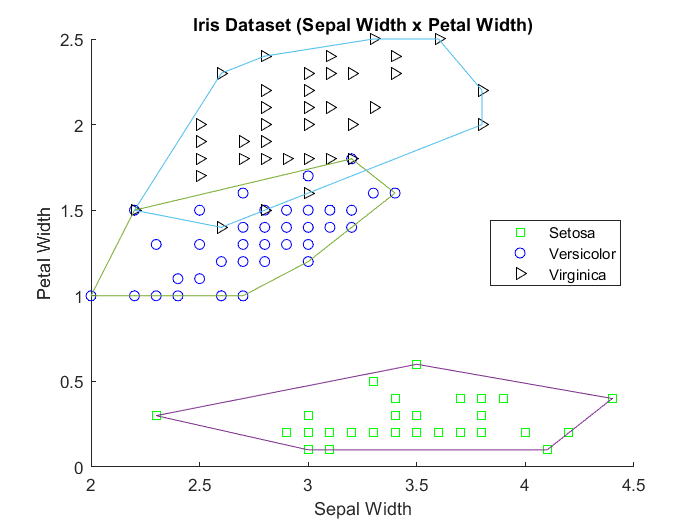

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Permutation 2 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

scatter(Species1(2,:), Species1(4,:),'gs'); xlabel('Sepal Width') ;ylabel('Petal Width'); 
hold on;
scatter(Species2(2,:), Species2(4,:),'bo');
scatter(Species3(2,:), Species3(4,:),'k>');

% Plot convex hulls around unique specie classes
[k,~] = convhull(Species1(2,:), Species1(4,:));
plot(Species1(2,k),Species1(4,k));

[k,~] = convhull(Species2(2,:), Species2(4,:));
plot(Species2(2,k),Species2(4,k));

[k,~] = convhull(Species3(2,:), Species3(4,:));
plot(Species3(2,k),Species3(4,k));

title('Iris Dataset (Sepal Width x Petal Width)')
legend('Setosa','Versicolor','Virginica','Location',"east")
hold off

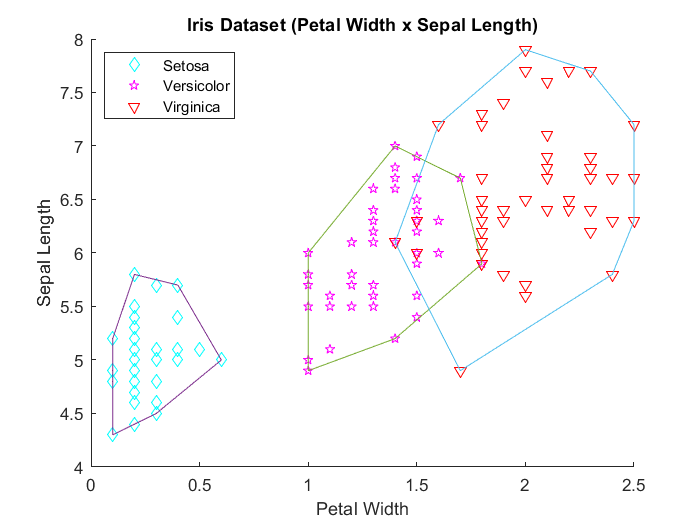

%%%%%%%%%%%%%%%%%%%%%%%%%% Combination PetalWidth x SepalLength %%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Permutation 1 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

scatter(Species1(4,:), Species1(1,:),'cd'); xlabel('Petal Width') ;ylabel('Sepal Length'); 
hold on;
scatter(Species2(4,:), Species2(1,:),'mp');
scatter(Species3(4,:), Species3(1,:),'rv');

% Plot convex hulls around unique specie classes
[k,~] = convhull(Species1(4,:), Species1(1,:));
plot(Species1(4,k),Species1(1,k));

[k,~] = convhull(Species2(4,:), Species2(1,:));
plot(Species2(4,k),Species2(1,k));

[k,~] = convhull(Species3(4,:), Species3(1,:));
plot(Species3(4,k),Species3(1,k));

title('Iris Dataset (Petal Width x Sepal Length)')
legend('Setosa','Versicolor','Virginica','Location',"northwest")
hold off

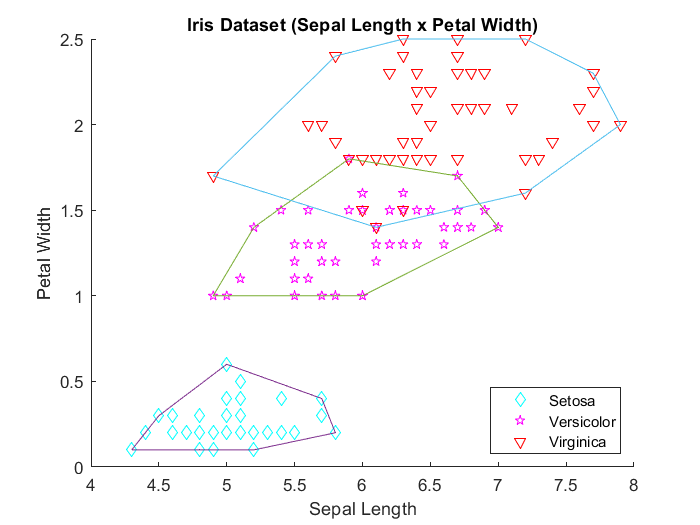

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Permutation 2 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

scatter(Species1(1,:), Species1(4,:),'cd'); xlabel('Sepal Length') ;ylabel('Petal Width'); 
hold on;
scatter(Species2(1,:), Species2(4,:),'mp');
scatter(Species3(1,:), Species3(4,:),'rv');

% Plot convex hulls around unique specie classes
[k,~] = convhull(Species1(1,:), Species1(4,:));
plot(Species1(1,k),Species1(4,k));

[k,~] = convhull(Species2(1,:), Species2(4,:));
plot(Species2(1,k),Species2(4,k));

[k,~] = convhull(Species3(1,:), Species3(4,:));
plot(Species3(1,k),Species3(4,k));

title('Iris Dataset (Sepal Length x Petal Width)')
legend('Setosa','Versicolor','Virginica','Location',"southeast")
hold off

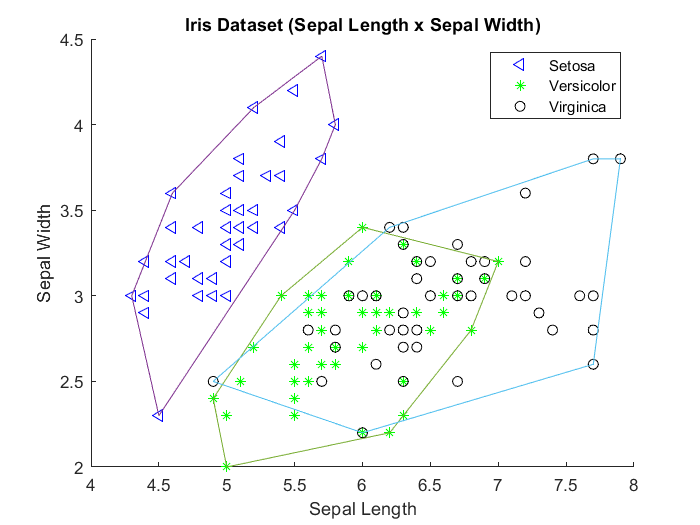

%%%%%%%%%%%%%%%%%%%%%%%%%%%% Combination SepalLength x SepalWidth %%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Permutation 1 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

scatter(Species1(1,:), Species1(2,:),'b<'); xlabel('Sepal Length') ;ylabel('Sepal Width'); 
hold on;
scatter(Species2(1,:), Species2(2,:),'g*');
scatter(Species3(1,:), Species3(2,:),'ko');

% Plot convex hulls around unique specie classes
[k,~] = convhull(Species1(1,:), Species1(2,:));
plot(Species1(1,k),Species1(2,k));

[k,~] = convhull(Species2(1,:), Species2(2,:));
plot(Species2(1,k),Species2(2,k));

[k,~] = convhull(Species3(1,:), Species3(2,:));
plot(Species3(1,k),Species3(2,k));

title('Iris Dataset (Sepal Length x Sepal Width)')
legend('Setosa','Versicolor','Virginica','Location',"northeast")
hold off

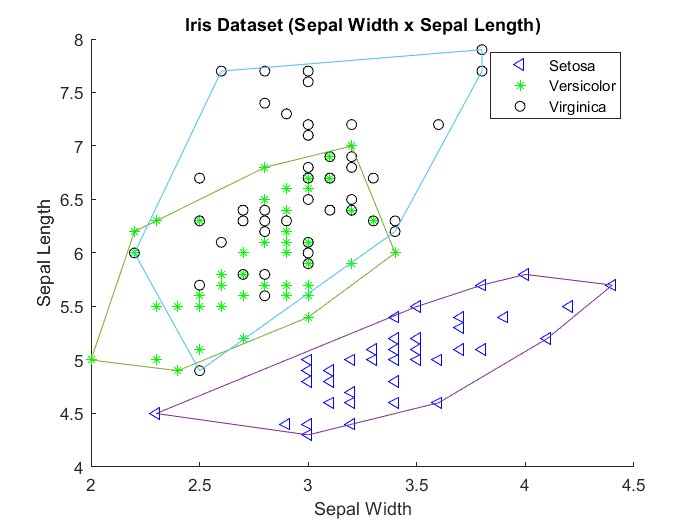

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Permutation 2 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

scatter(Species1(2,:), Species1(1,:),'b<'); xlabel('Sepal Width') ;ylabel('Sepal Length'); 
hold on;
scatter(Species2(2,:), Species2(1,:),'g*');
scatter(Species3(2,:), Species3(1,:),'ko');

% Plot convex hulls around unique specie classes
[k,~] = convhull(Species1(2,:), Species1(1,:));
plot(Species1(2,k),Species1(1,k));

[k,~] = convhull(Species2(2,:), Species2(1,:));
plot(Species2(2,k),Species2(1,k));

[k,~] = convhull(Species3(2,:), Species3(1,:));
plot(Species3(2,k),Species3(1,k));

title('Iris Dataset (Sepal Width x Sepal Length)')
legend('Setosa','Versicolor','Virginica','Location',"northeast")
hold off

### Task 2(c) 

Is classification of Iris flowers is a linearly separable or a non-separable problem? 

    *- This is a non-linearly separable problem, this is due to the fact that even though, the specie Setosa can be linearly seperated using a single seperating hyperplane in any and all of the plots shown previously in Task 2(b). However, an overlap always exists between the other two species (Versicolor and Virginica), disallowing the linear seperation using a single hyperplane and therefore making the problem non-linearly separable as more than a single linear seperating line would often be required to perform a classification.*

### Task 2(d) 

Using the Back-Propagation algorithm for a single hidden layer ANN with sigmoid activation function, find the weights and bias of the ANN which can perform this classification. 

[*You ****must**** the sigmoid back-propagation (BP) blackbox function provided at the end of this file, to perform classification of Iris dataset. ****Use of Matlab ANN toolbox, for example ***`patternnet, trainNetwork, feedforwardnet `***and others is not permitted.***]  

[Use parameter number of hidden neuron = 5, $\eta=0.0625$, $\alpha = 0.2$ and $tol=5\times10^{-3}$]

clear; clc;
rng(1); % DO NOT MODIFY THIS LINE

% Load Matlab's Iris Dataset
[A,D] = iris_dataset;

% weight matrix of from input to hidden layer with required size
Wih_guess = rand(5);

% weight matrix of from hidden to output layer
Whj_guess = ones(6,3);

% Function parameters
lambda = 1 ;
num_hidden_neuron = 5;
eta = 0.0625;
alpha = 0.2;
tol = 5*10^-3;

% Backpropagation sigmoid function
[Wih,Whj] = backpropagation_1hiddenLayer_blackbox(A,...
    D,...
    lambda,...
    eta,...
    alpha,...
    tol,...
    num_hidden_neuron,...
    Wih_guess,...
    Whj_guess)

Epoch : 10000 | MSE : 1.175e-02 
Epoch : 20000 | MSE : 8.564e-03 
Epoch : 30000 | MSE : 8.414e-03 
Epoch : 40000 | MSE : 8.377e-03 
Epoch : 50000 | MSE : 1.226e-02 
Epoch : 60000 | MSE : 8.594e-03 
Epoch : 70000 | MSE : 8.003e-03 
Epoch : 80000 | MSE : 8.560e-03 
Epoch : 90000 | MSE : 8.404e-03 
Epoch : 100000 | MSE : 7.718e-03 
Epoch : 110000 | MSE : 1.116e-02 


Wih =   -95.9977    0.5141    0.0834    0.7307    0.8009
  -28.8500    0.6070   -0.5023    0.8174    0.9764
  -32.2219    2.5685   -1.3096    0.6343    0.3095
   57.1932   -4.2600    2.9695    0.6581    0.7164
   52.2127   -1.6843    0.9400    0.3655    0.8852


Whj =    -1.3603    1.4233   -1.7747
   -2.0546  -10.1277   10.1290
   11.3978  -12.2972   -2.5593
   -2.5455    2.2397   -1.3687
   -1.4802    1.3948   -1.5776
   -1.3712    1.4291   -1.7668



$$\underline{\underline{W}}_{ih}= 
\pmatrix{ -95.9977, 0.5141, 0.0834, 0.7307, 0.8009 \cr
-28.8500, 0.6070, -0.5023, 0.8174, 0.9764\cr 
-32.2219, 2.5685, -1.3096, 0.6343, 0.3095 \cr
57.1932, -4.2600, 2.9695, 0.6581, 0.7164
\cr
52.2127, -1.6843, 0.9400, 0.3655, 0.8852
}$$



$$\underline{\underline{W}}_{hj} = 
\pmatrix{
-1.3603, 1.4233, -1.7747 \cr
-2.0546, -10.1277, 10.1290 \cr
11.3978, -12.2972, -2.5593 \cr
-2.5455, 2.2397, -1.3687 \cr
-1.4802, 1.3948, -1.5776 \cr
-1.3712, 1.4291, 1.7668
}$$


where $\underline{\underline{W}}_{ih}$ is the weight of between the input and hidden layer and $\underline{\underline{W}}_{hj}$ is the weight of between the hidden and output layer.

The MSE based on the calculated $\underline{\underline{W}}_{ih}$ and $\underline{\underline{W}}_{hj}$,


$$MSE = 7.718e-03$$


### Task 2(e) 

Now, consider that the output signal from the output layer. Using the weight obtained in Task 2(d), plot the confusion matrix.  

*Hint: *`doc plotconfusion`

%% test
[~,Nk] = size(A);
sigmoid =@(lambda,x) 1./(1+exp(-lambda.*x)); % sigmoid function

Zk = transpose(Wih) * [ones(1,Nk);A]; % hidden layer activation state
psiZk = [ones(1,Nk); sigmoid(lambda,Zk)]; % signal of hidden layer for each k

Yk = transpose(Whj) * psiZk; % output layer activation state

psiYk = sigmoid(lambda,Yk); % signal from output layer

plotconfusion(D,psiYk);
title("Classification of Iris Species(Confusion Matrix)")

Discuss what does the confusion matrix show you about the performance your ANN!

**    - ***The confusion matrix illustrates that out of the three classes of species, the overall accuracy of the classification is 99.3% correct. Which is overall average of the performance of each of the individual species classifications combined. As such, for the Setosa specie (Class 1) and Virginica specie (Class 3), there was a 100% success rate in identifying said specie. However, since the Virginica and Versicolor flowers overlap (recall previously), some confusion can be observed in correctly identifying Versicolor flowers ~ 98% success rate i.e. 1 Versicolor flower is mistaken for a Virginica flower.*

## **Question 3 [20%]**

### Task 3(a)

Modify the Sigmoid Back-Propagation algorithm for a single hidden layer ANN, so now the activation function of the neuron is tan hyperbolic function.

[*I have provided a function template at the bottom of this file to be completed. ****Use of Matlab ANN toolbox, for example ***`patternnet, trainNetwork, feedforwardnet `***and others is not permitted.***]

List and describe the modification done:

***Modifications:***

- **tanh =@(lambda,x) (exp(lambda.*2.*x)-1)./(exp(lambda.*2.*x)+1);**

- **dtanh =@(lambda,x) lambda * ( 1 - tanh(lambda,x).^2 ); **

***Description of modifications:***

***    - The previous modifications were performed to the sigmoid activation function and its derivative, they were replaced by the following:***

- ***The Hyperbolic Tangent Function: tanh(x) = ***$\frac{\sinh \left(x\right)}{\cosh \left(x\right)}$*** = ***$\frac{e^x -e^{-x} }{e^x +e^{-x} }$*** = ***$\frac{e^{2x} -1}{e^{2x} +1}$ 

- ***Its derivative: tanh'(x) = ***$1-{\textrm{tanh}\left(x\right)}^2$

    ***- Changed variable names of all following occurences of the activation functions from sigmoid & dsigmoid to tanh & dtanh.***

### Task 3(b)

Now, use the Back-Propagation algorithm for a single hidden layer ANN with tan hyperbolic activation function, to find the weights and bias of the ANN which can perform the XNOR operations in Question 1. 

[*You ****must**** the tanh back-propagation (BP) blackbox function from Task 3(a), to perform this Task. ****Use of Matlab ANN toolbox, for example ***`patternnet, trainNetwork, feedforwardnet `***and others is not permitted.***] 

You *may* need to modify the operational parameter $\eta$ and $\alpha$ so that you achieve the desired performance, I let you experimenting to find such appropriate parameters. 

Describe your experiment strategies to achieve such objective!

*    - Eta and Alpha were first both set to really low values, however it was then observed that the learning process of the algorithms becomes significantly longer, upon increasing the learning rate to a high value the accuracy of the performance dropped, as a result of overshooting, upon modifiying and remodifying these two parameters, the following values were found to produce an Artificial Neural Network capable of performing the XNOR operation, with a 100% accuracy with a reasonable learning time.*

clear; clc;
rng(1); % DO NOT MODIFY THIS LINE

% Input set
A = [ 0 0 1 1;...    %a_1
    0 1 0 1; ];      %a_2

% Desired output, i.e. Teaching set
D = [ 1 0 0 1 ];

% weight matrix of from input to hidden layer
Wih_guess = [ 1 -1 ;...    % first column is the weight of OR gate
    1 -1 ;...              % second column is the weight of NAND gate
    1 -1];

% weight matrix of from hidden to output layer
Whj_guess = [-2;...   % first column is the weight of AND gate
    1;...
    1];

% Function parameters
lambda = 1 ;
num_hidden_neuron = 2;
eta = 0.05;     % Modify
alpha = 0.2;    % Modify
tol = 1*10^-4;

% Backpropagation Hyperbolic Tangent function
[Wih,Whj] = backpropagation_1hiddenLayer_blackbox_tanh(A,...
    D,...
    lambda,...
    eta,...
    alpha,...
    tol,...
    num_hidden_neuron,...
    Wih_guess,...
    Whj_guess)

Epoch : 10000 | MSE : 8.135e-04 
Epoch : 20000 | MSE : 5.185e-04 
Epoch : 30000 | MSE : 2.680e-04 
Epoch : 40000 | MSE : 2.470e-04 
Epoch : 50000 | MSE : 2.115e-04 


Wih =    -0.8265    1.3448
    0.9521   -3.2216
    0.9545   -3.2290


Whj =     2.6872
    4.1154
    3.3382



$$\underline{\underline{W}}_{ih}= 
\pmatrix{ -0.8265, 1.3448 \cr
0.9521, -3.2216 \cr
0.9545, -3.2290
}$$



$$\underline{\underline{W}}_{hj} = 
\pmatrix{
2.6872 \cr
4.1154 \cr
3.3382
}$$


where $\underline{\underline{W}}_{ih}$ is the weight of between the input and hidden layer and $\underline{\underline{W}}_{hj}$ is the weight of between the hidden and output layer.

The MSE based on the calculated $\underline{\underline{W}}_{ih}$ and $\underline{\underline{W}}_{hj}$,


$$MSE = 2.115e-04$$


### Task 3(c) 

Give evidence that your weight can perform the required operation:

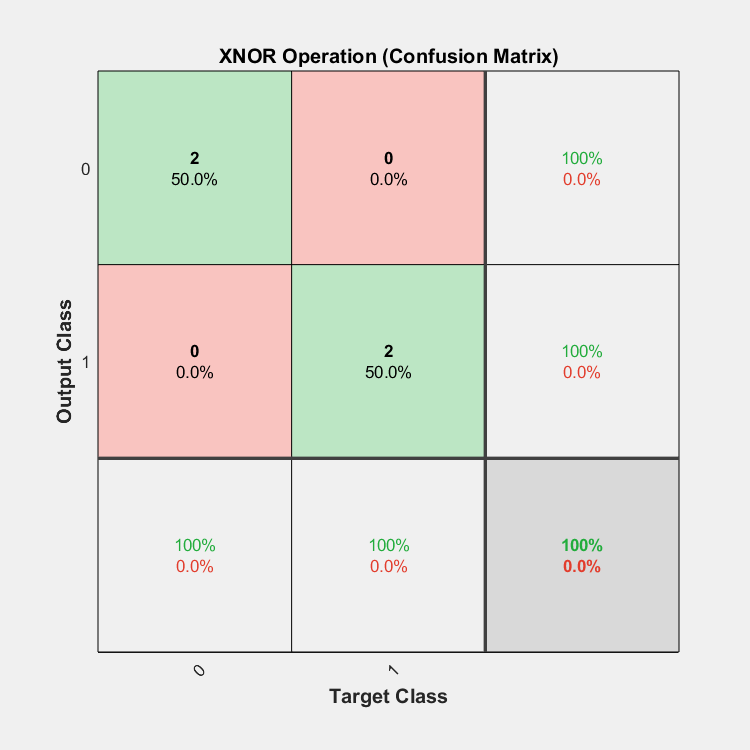

% test
[~,Nk] = size(A);
tanh =@(lambda,x) (exp(lambda.*2.*x)-1)./(exp(lambda.*2.*x)+1); % sigmoid function

Zk = transpose(Wih) * [ones(1,Nk);A]; % hidden layer activation state
psiZk = [ones(1,Nk); tanh(lambda,Zk)]; % signal of hidden layer for each k

Yk = transpose(Whj) * psiZk; % output layer activation state

psiYk = tanh(lambda,Yk); % signal from output layer

finerr = sum((D - psiYk).^2,'all'); % final error Instataneous error

plotconfusion(D,psiYk);
title("XNOR Operation (Confusion Matrix)")

## Question 4 - Artificial Neural Network Application for Hand-Written Roman Number Image Recognition in Black and White [25%]

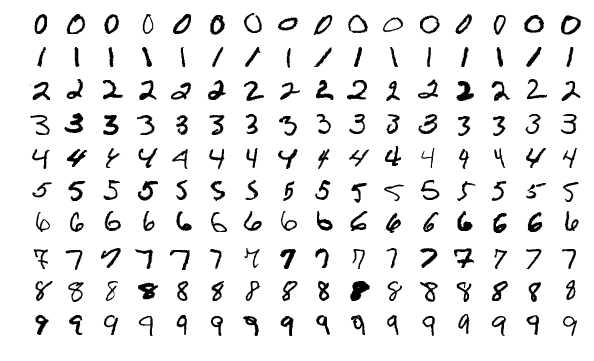

A folder named "handwritten_number_rgb" which contains 301 png files has been included as dataset for Question 4. 

Each png is a 28*28 RGB pixel image.

In addition in this folder, the file index.csv give information of the number written in each file for your convenience. 

**Although the png files given are grey-scalled, for this question image recognition must be done on black and white images.** 

**Use of Matlab ANN toolbox, for example **`patternnet, trainNetwork, feedforwardnet, `**and others is not permitted.** 

Describe your finding!

*General Hint: *

*(1) *`doc imread, doc imbinarize`* and *`doc reshape`

`(2)`* assign each pixel to each input neuron*

*(3) Encode your "number". For example, number "0", *$\underline{d}=[1,0,0,0,0,0,0,0,0]^T$, *number "1", *$\underline{d}=[0,1,0,0,0,0,0,0,0]^T$, *number "2", *$\underline{d}=[0,0,1,0,0,0,0,0,0]^T$, and so on    

*(4) how do I know how good is my image recognition? [Hint: confusion matrix]*

*(5) I will test your code using my image database. My image database simillar to that in "handwritten_number_rgb" folder but I have more images, so do not hardcoded the number of images to 301. *

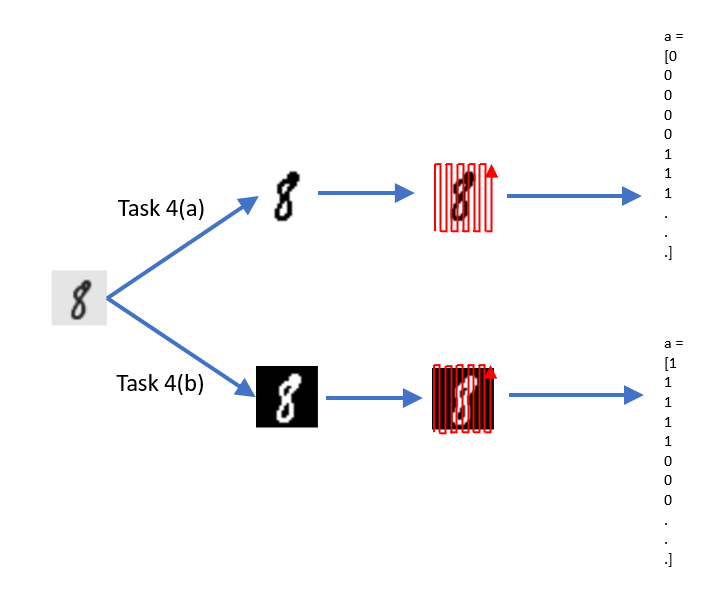

**Figure for Question 4**: Illustration depicting the pre-processing of the PNG number files for classification

### Task 4(a)

Following the route Task 4(a) in Figure for Question 4, obtain a single-hidden layer ANN which can perfrom such image classification. 

- You are allowed to use either the sigmoid or the tanh back-propagation code

- You will need to do some experimentation to find an appropriate set of parameter such as number of hidden-layer neuron, $\eta$ and $\alpha$  

clear; clc;
rng(1); % DO NOT MODIFY THIS LINE

% for example: "C:\Users\username\Desktop\tmnist_bundle_rgb\tmnist_bundle_rgb"
mainDirectory = "C:\Users\youse\OneDrive\Desktop\" + ...
    "Artificial Intelligence and Intelligent Systems\2021_CWK2_ANN\handwritten_number_rgb"; 
% I will modify mainDirectory to my dataset directory, thus make sure your code will compliant

% Obtaining Picture Number Indexes
numIdx = readtable(strcat(mainDirectory, "\index.csv"));
numIdx = table2array(numIdx(:,1));

% Encoded binaries of numbers 0-9
D_initial = [ 1 0 0 0 0 0 0 0 0 0 ; % 0
    0 1 0 0 0 0 0 0 0 0 ;           % 1
    0 0 1 0 0 0 0 0 0 0 ;           % 2
    0 0 0 1 0 0 0 0 0 0 ;           % 3
    0 0 0 0 1 0 0 0 0 0 ;           % 4
    0 0 0 0 0 1 0 0 0 0 ;           % 5
    0 0 0 0 0 0 1 0 0 0 ;           % 6
    0 0 0 0 0 0 0 1 0 0 ;           % 7
    0 0 0 0 0 0 0 0 1 0 ;           % 8
    0 0 0 0 0 0 0 0 0 1 ];          % 9

for i=1:numel(dir(fullfile(mainDirectory,'\imgs\*.png*')))
    
    % Create a cell array of the images
    imgs{i}=imread(strcat(mainDirectory,'\imgs\img_',num2str(i-1)),"png");
    
    % Create a cell array of the Grayscale of the RGB images
    imgsGray{i} = rgb2gray(imgs{i});
    
    % Create a cell array of the binary equivalent of the Grayscale images
    imgsBinary{i}=imbinarize(imgsGray{i});
    
    % Create Temporary variable for use in following conditional statement
    Temp = reshape(imgsBinary{i},[784,1]);
    
    % Pre-process the images converting them to black digits with white backgrounds
    if sum(Temp) <= 784/2
        imgsProcessed{i} = ~imgsBinary{i};
    else
        imgsProcessed{i} = imgsBinary{i};
    end
    
    % Input matrix
    AA = reshape(imgsProcessed{i},784,[]);
    A{i} = AA(:,1);
    
end


% Construct Desired output Matrix
for x=1:i
    
    for n=1:10
        
        % Compare n to the number index of the current image
        if numIdx(x,1) == n-1
            
            % Obtain the output column corresponding to the number found to match
            DesiredOutput = D_initial(n,:); 
            
        end
        
    end
    
    D(:,x) = DesiredOutput; % Update the corresponding output column
    
end

% Function Parameters
A = cell2mat(A);
lambda = 1 ;
eta = 0.0001;
alpha = 0.3;
tol = 7*10^-3;
num_hidden_neuron = 10;

% Modify Rand Parameters
rng(0,'twister');
a = -0.5;
b = 0.5;

% Initial weight guesses
Wih_guess = (b-a).*rand(785,10) + a;
Whj_guess = (b-a).*rand(11,10) + a;

% whos A
% whos D

% Backpropagation Sigmoid function
[Wih,Whj] = backpropagation_1hiddenLayer_blackbox(A,...
    D,...
    lambda,...
    eta,...
    alpha,...
    tol,...
    num_hidden_neuron,...
    Wih_guess,...
    Whj_guess)

Epoch : 10000 | MSE : 4.992e-02 
Epoch : 20000 | MSE : 2.820e-02 
Epoch : 30000 | MSE : 1.542e-02 
Epoch : 40000 | MSE : 9.127e-03 


Wih =     0.3187   -0.1730   -0.2313   -0.2118    0.3682    0.4361    0.1323   -0.0271   -0.1102   -0.1793
    0.4098    0.0973   -0.2646   -0.1128   -0.3920   -0.3224    0.0748   -0.4028   -0.2012    0.1265
   -0.3690    0.2307   -0.2630   -0.0884   -0.1507    0.3919    0.4017   -0.0808   -0.2109   -0.0190
    0.4174   -0.4058   -0.3520   -0.1977   -0.2634   -0.1040   -0.2786    0.2606   -0.2505   -0.1884
    0.1363   -0.3827    0.4503    0.1846    0.0550   -0.1093   -0.4889   -0.3667   -0.4757    0.3514
   -0.3985    0.0390    0.4295   -0.4173    0.1074   -0.2204    0.3878    0.2054    0.4160    0.0895
   -0.2175   -0.0253    0.3126   -0.1071   -0.2045    0.3760   -0.2576   -0.1654   -0.0235   -0.4105
    0.0509    0.3799    0.2221   -0.2140    0.2928    0.2496   -0.2479    0.1367    0.1014   -0.2147
    0.4615    0.2884   -0.3303   -0.2027    0.2903   -0.0440    0.1482   -0.3100   -0.1614   -0.3101
    0.4689    0.2238   -0.1457   -0.4036    0.2758    0.2178   -0.1882   -0.0254    0

Whj =    -0.8055   -0.4911   -1.9919   -0.3392   -2.4518   -0.1776    0.0400   -1.8002   -1.1786   -0.8631
    0.2305   -0.0552   -1.1135    0.0370    0.0788   -0.0548   -0.2104    0.0021    1.3476   -0.2189
    1.6157    2.5652   -0.5839   -2.0241   -2.3359   -0.3613   -1.5478    3.9881   -1.8891   -3.5280
   -4.6092    0.3202    0.3938    0.1429   -1.4107    0.1821    0.4585   -0.5822   -0.7550    0.2930
   -0.7921   -1.6272    0.3847   -2.8334    3.0171    1.7503   -1.4880    1.8909   -1.7923    1.8791
   -0.1700   -0.5351   -1.6742   -1.2431   -2.1279   -0.6132   -0.2095   -1.7051   -0.5137   -0.4384
   -0.5510    0.7368   -1.2904    0.4939    0.8370   -1.1048   -4.5419   -0.3435    1.0718    0.4179
    0.4194    0.7700    0.0524   -3.6794    3.5703   -0.2926    1.5092   -2.6909    0.2883   -3.9499
    0.6646   -3.6869   -0.2035    0.8571    0.2238   -3.8578    0.9470    0.5763   -0.5907    0.6726
    1.6739   -3.2723    2.4422    2.7345   -2.4601    2.8838   -1.0802   -1.7531   -1

$\underline{\underline{W}}_{ih}= 
$ Find in Wih_Task4a.xlsx

$\underline{\underline{W}}_{hj} = 
$ Find in Whj_Task4a.xlsx

where $\underline{\underline{W}}_{ih}$ is the weight of between the input and hidden layer and $\underline{\underline{W}}_{hj}$ is the weight of between the hidden and output layer.

The MSE based on the calculated $\underline{\underline{W}}_{ih}$ and $\underline{\underline{W}}_{hj}$,


$$MSE = 9.127e-03$$


**Plot the confusion matrix. **

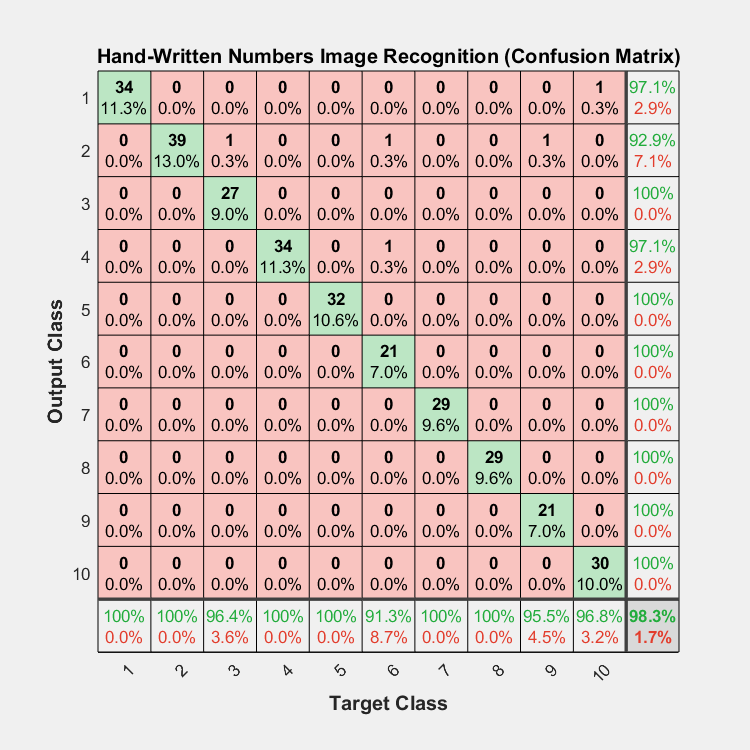

%% test
[~,Nk] = size(A);
sigmoid =@(lambda,x) 1./(1+exp(-lambda.*x)); % sigmoid function

Zk = transpose(Wih) * [ones(1,Nk);A]; % hidden layer activation state
psiZk = [ones(1,Nk); sigmoid(lambda,Zk)]; % signal of hidden layer for each k

Yk = transpose(Whj) * psiZk; % output layer activation state

psiYk = sigmoid(lambda,Yk); % signal from output layer

finerr = sum((D - psiYk).^2,'all'); % final error Instataneous error

plotconfusion(D,psiYk);
title("Hand-Written Numbers Image Recognition (Confusion Matrix)")
hold off;

### Task 4(b)

Following the route Task 4(b) in Figure for Question 4, obtain a single-hidden layer ANN which can perfrom such image classification. 

- You are allowed to use either the sigmoid or the tanh back-propagation code

- You may need to do some experimentation to find an appropriate set of parameter such as number of hidden-layer neuron, $\eta$ and $\alpha$  

clear; clc;
rng(1); % DO NOT MODIFY THIS LINE

% for example: "C:\Users\username\Desktop\tmnist_bundle_rgb\tmnist_bundle_rgb"
mainDirectory = "C:\Users\youse\OneDrive\Desktop\" + ...
    "Artificial Intelligence and Intelligent Systems\2021_CWK2_ANN\handwritten_number_rgb"; 
% I will modify mainDirectory to my dataset directory, thus make sure your code will compliant

% Obtaining Picture Number Indexes
numIdx = readtable(strcat(mainDirectory, "\index.csv"));
numIdx = table2array(numIdx(:,1));

% Encoded binaries of numbers 0-9
D_initial = [ 1 0 0 0 0 0 0 0 0 0 ; % 0
    0 1 0 0 0 0 0 0 0 0 ;           % 1
    0 0 1 0 0 0 0 0 0 0 ;           % 2
    0 0 0 1 0 0 0 0 0 0 ;           % 3
    0 0 0 0 1 0 0 0 0 0 ;           % 4
    0 0 0 0 0 1 0 0 0 0 ;           % 5
    0 0 0 0 0 0 1 0 0 0 ;           % 6
    0 0 0 0 0 0 0 1 0 0 ;           % 7
    0 0 0 0 0 0 0 0 1 0 ;           % 8
    0 0 0 0 0 0 0 0 0 1 ];          % 9

for i=1:numel(dir(fullfile(mainDirectory,'\imgs\*.png*')))
    
    % Create a cell array of the images
    imgs{i}=imread(strcat(mainDirectory,'\imgs\img_',num2str(i-1)),"png");
    
    % Create a cell array of the Grayscale of the RGB images
    imgsGray{i} = rgb2gray(imgs{i});
    
    % Create Temporary variable for use in following conditional statement
    imgsBinary{i}=imbinarize(imgsGray{i});
    
    % Create Temporary variable for use in following conditional statement
    Temp = reshape(imgsBinary{i},[784,1]);
    
    % Pre-process the images converting them to white digits with black backgrounds
    if sum(Temp) >= 784/2
        imgsProcessed{i} = ~imgsBinary{i};
    else
        imgsProcessed{i} = imgsBinary{i};
    end
    
    % Input matrix
    AA = reshape(imgsProcessed{i},784,[]);
    A{i} = AA(:,1);
    
end


% Construct Desired output Matrix
for x=1:i
    
    for n=1:10
        
        % Compare n to the number index of the current image
        if numIdx(x,1) == n-1    
            
            % Obtain the output column corresponding to the number found to match
            DesiredOutput = D_initial(n,:);
            
        end
        
    end
    
    D(:,x) = DesiredOutput; % Update the corresponding output column
    
end

% Function Parameters
A = cell2mat(A);
lambda = 1 ;
eta = 0.0001;
alpha = 0.3;
tol = 7*10^-3;
num_hidden_neuron = 10;

% Modify Rand Parameters
rng(0,'twister');
a = -0.5;
b = 0.5;

% Initial weights guess
Wih_guess = (b-a).*rand(785,10) + a;
Whj_guess = (b-a).*rand(11,10) + a;

% whos A
% whos D

% Backpropagation Sigmoid function
[Wih,Whj] = backpropagation_1hiddenLayer_blackbox(A,...
    D,...
    lambda,...
    eta,...
    alpha,...
    tol,...
    num_hidden_neuron,...
    Wih_guess,...
    Whj_guess)

Epoch : 10000 | MSE : 4.253e-02 
Epoch : 20000 | MSE : 2.330e-02 
Epoch : 30000 | MSE : 1.324e-02 


Wih =     0.5643   -0.4313   -0.2569    0.0575    0.2658    0.6386    0.3955    0.2969   -0.2332   -0.1904
    0.4058    0.1079   -0.2585   -0.1036   -0.3867   -0.3305    0.0676   -0.4410   -0.2242    0.1075
   -0.3730    0.2413   -0.2569   -0.0792   -0.1454    0.3837    0.3945   -0.1190   -0.2339   -0.0380
    0.4134   -0.3952   -0.3458   -0.1885   -0.2581   -0.1121   -0.2858    0.2224   -0.2735   -0.2074
    0.1324   -0.3721    0.4564    0.1938    0.0603   -0.1174   -0.4961   -0.4049   -0.4987    0.3324
   -0.4025    0.0495    0.4357   -0.4081    0.1127   -0.2285    0.3806    0.1672    0.3930    0.0705
   -0.2215   -0.0148    0.3187   -0.0979   -0.1992    0.3679   -0.2649   -0.2036   -0.0465   -0.4295
    0.0469    0.3905    0.2283   -0.2048    0.2981    0.2415   -0.2551    0.0986    0.0784   -0.2337
    0.4575    0.2990   -0.3242   -0.1935    0.2956   -0.0521    0.1409   -0.3481   -0.1844   -0.3291
    0.4649    0.2343   -0.1396   -0.3944    0.2811    0.2096   -0.1955   -0.0636    0

Whj =    -0.9830   -0.6592   -0.8747   -0.1423   -0.8485   -1.0435   -0.8094   -1.4934   -1.6438   -1.0410
    1.2890    1.7649   -0.8628    1.7854   -1.9510   -0.1725   -1.3931   -1.0425   -1.9775   -2.6256
    0.5375   -1.7278   -0.6309    0.2918    0.8204    0.6993    1.2398   -3.1689    0.5374   -2.0551
   -0.5849   -3.0855    1.1518    0.0092    0.2815   -1.0019    0.2462   -0.2606   -3.0577    0.1769
   -2.4994    1.1718    0.8840   -0.6014   -0.2569    0.7762   -3.1297    0.9794    0.2969   -0.1527
    0.7609   -0.3879    0.7851   -2.9347   -0.2297   -1.6000   -0.5724   -1.6808    0.3200    0.6710
    0.2165    0.8471    0.4883   -3.3347    0.4904   -0.0197    0.4294    1.7420    0.1110   -3.6226
   -2.6134    0.7493   -4.3387   -0.2808    0.9109   -1.6644    1.4791    0.6774   -0.7176    0.3570
    1.4482   -0.1838   -1.9110   -1.6672   -3.2640    1.3618   -0.3322    2.2876   -1.9545    1.0562
   -2.3177    0.1953    1.0967    1.0445   -3.9606    0.2171    0.6404   -2.4776    1

$\underline{\underline{W}}_{ih}= 
$ Find in Wih_Task4b.xlsx

$\underline{\underline{W}}_{hj} = 
$ Find in Whj_Task4b.xlsx

where $\underline{\underline{W}}_{ih}$ is the weight of between the input and hidden layer and $\underline{\underline{W}}_{hj}$ is the weight of between the hidden and output layer.

The MSE based on the calculated $\underline{\underline{W}}_{ih}$ and $\underline{\underline{W}}_{hj}$,


$$MSE = 1.324e-02$$


**Plot the confusion matrix. **

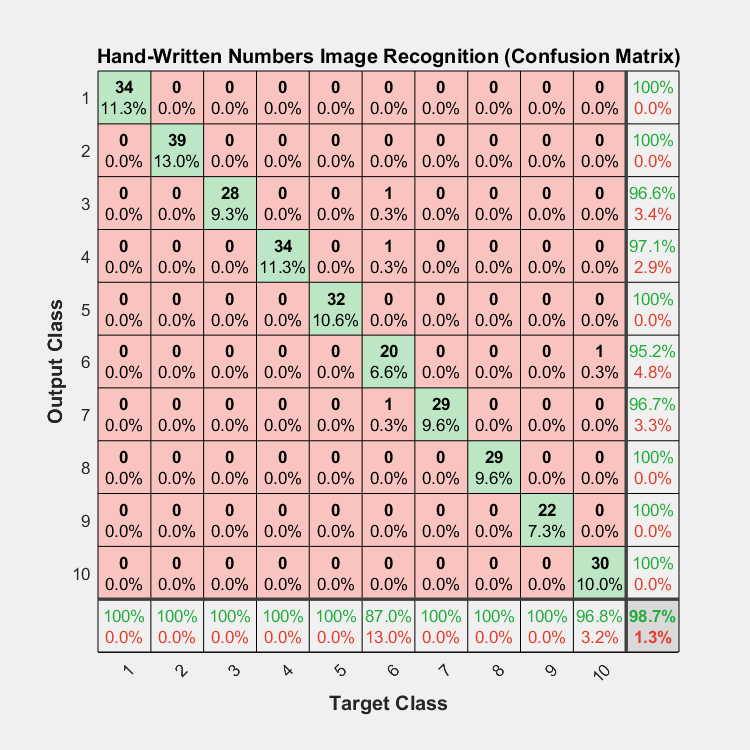

%% test
[~,Nk] = size(A);
sigmoid =@(lambda,x) 1./(1+exp(-lambda.*x)); % sigmoid function

Zk = transpose(Wih) * [ones(1,Nk);A]; % hidden layer activation state
psiZk = [ones(1,Nk); sigmoid(lambda,Zk)]; % signal of hidden layer for each k

Yk = transpose(Whj) * psiZk; % output layer activation state

psiYk = sigmoid(lambda,Yk); % signal from output layer

finerr = sum((D - psiYk).^2,'all'); % final error Instataneous error

plotconfusion(D,psiYk);
title("Hand-Written Numbers Image Recognition (Confusion Matrix)")

### Task 4(c)

Following Task 4(a) and Task 4(b), discuss: 

- **Which number can be easily disciminate, which ones not? Why?  **

- *The numbers that were easily discriminated were the digits 0,1,3,4,6,7. While the numbers that results in some confusion were 5 (mostly), along with 2,8,9. The reason for this may be the shape of the digit itself, for instance, all the digits that are easily discriminated have unique and distinct features which do not recur in any of the other numbers. On the other hand, the digits that caused confusion were the ones that could possible produce a pattern that can be mistaken for another number. An example of this is that 5 is often mistaken for a 2 or a 3 & 9 is often mistaken for 0. This comes down to the uniqueness of the pattern a digit produces, and intuitively, by looking at 5, one can see that the pattern it produces is probably not substaintially different from that produced by 3, hence the confusion.*

- **Which preprocessing (Task 4(a) or Task 4(b)) yield to a better performance? Why?**

- *Task 4(b) was found to yield the better performance. Although, the difference in performance is a mere 0.5%, one can still make an interesting observation by looking at the individual classifications. In the confusion matrix of 4(b), one can see that mistakes only ever occured with 2 numbers, 5 & 9. While in the confusion matrix of Task 4(a), mistakes occured in classifying numbers 2, 5, 8 & 9. This observation draws a very important conclusion, which is that shifting digits to white against a black background, increases the chance of classifying them. (This does not hold true only for the digit 5)*

- **List and give reason what else can you do to improve the performance!**

- *The tolerance can be reduced - this would result in a longer teaching time, but will also result in a lower Mean Squared Error, this means that the weights produced at the end of running the function would yield a more accurate classification, similarly the learning rate and momentum of learning can also be modified and tested in an attempt to improve performance. An alternative way to improve performance would be to connect both the Neural Networks in a way such that the predicted value is compared from both networks and only accepted as correct if it matches, this will decrease the chance of error therefore improving the performance, but will increase the complexity of the network.*

## [PROVIDED] Back-Propagation function for a single hidden ANN layer with sigmoid activation function

function [Wih,Whj] = backpropagation_1hiddenLayer_blackbox(A,...
    D,...
    lambda,...
    eta,...
    alpha,...
    tol,...
    num_hidden_neuron,...
    Wih_guess,...
    Whj_guess)
% backpropagation_1hiddenLayer_blackbox  Find weights for an ANN with 1
% hidden layer
% [Wih,Whj] = backpropagation_1hiddenLayer_blackbox(A,...
%                                                   D,...
%                                                   lambda,...
%                                                   eta,...
%                                                   alpha,...
%                                                   tol,...
%                                                   num_hidden_neuron,...
%                                                   Wih_guess,...
%                                                   Whj_guess)
% INPUT:
% A is the input parameter EXCLUDING bias, size = Dataset number x dimensions of input.
% D is the target vector.
% lambda is the sigmoid parameter
% eta is the learning rate
% alpha is the momentum
% tol is the tolerance
% num_hidden_neuron is the number of neuron in hidden layer
% Wih_guess is the guess for weight between the input and hidden layer
% Whj_guess is the guess for weight between the hidden and output layer
% OUTPUT:
% Wih is the weight between the input and hidden layer
% Whj is the weight between the hidden and output layer

%% Activation function
sigmoid =@(lambda,x) 1./(1+exp(-lambda.*x));    % sigmoid function

% Derivative of sigmoid function
dsigmoid =@(lambda,x) lambda * sigmoid(lambda,x) .* (1 - sigmoid(lambda,x)) ; 

%% some parameters
% N_k : total number of the pattern
[n,Nk] = size(A);
[p,Nk_temp] = size(D);
q = num_hidden_neuron;       % number of neuron in hidden layer
% n - q - p : architecture of the NN

if(Nk~=Nk_temp)
    error('error')
end

%% initialisation
Wih = Wih_guess; % start with the guess
Whj = Whj_guess;

if ~isequal([n+1,q],size(Wih))
    error('Size of the initial Wih is wrong')
end
if ~isequal([q+1,p],size(Whj))
    error('Size of the initial Whj is wrong')
end

DeltaWih = zeros(size(Wih));
DeltaWhj = zeros(size(Whj));

DeltaWih_past = zeros(size(Wih));
DeltaWhj_past = zeros(size(Whj));

psiZk = [1; ...
    zeros(q,1)];
psiYk = [zeros(p,1)];

xi_output = zeros(p,1);
xi_hidden = zeros(q+1,1);

%% working variables
sumError = 1;
MSE = 1;
epoch = 1;
max_epoch = 200000;

while MSE>tol
    
    if epoch>max_epoch
        Wih = rand(size(Wih_guess)); % start with new guess
        Whj = rand(size(Whj_guess));
        
        epoch = 0; %% reset epoch
    end
    
    sumError = 0;  % reset total error
    
    for k= 1:Nk
        
        %
        psiAk = [1;A(:,k)];                 % signal of input layer  SIZE (n+1) x 1
        
        Zk = transpose(Wih) * psiAk;        % hidden layer activation state  SIZE q x 1
        
        psiZk = [1; sigmoid(lambda,Zk)];   % signal of hidden layer for each k SIZE (q+1) x 1
        
        Yk = transpose(Whj) * psiZk;        % output layer activation state  SIZE p x 1
        
        psiYk = sigmoid(lambda,Yk);         % signal from output layer   SIZE p x 1
        
        %
        Ek = D(:,k) - psiYk;                % Instataneous error   SIZE p x 1
        
        % Errors and gradient at output neurons
        dEk_dpsiYk = -(Ek);                 % SIZE p x 1
        dpsiYk_dYk = dsigmoid(lambda,Yk);   % partial derivative of psi(Y_k)  SIZE p x 1
        dYk_dWhj = psiZk;                   % SIZE (q+1) x 1
        
        xi_output = dEk_dpsiYk.*dpsiYk_dYk;     % SIZE p x 1
        
        DeltaWhj =  - eta  * dYk_dWhj * transpose(xi_output)  ;   % SIZE (q+1) x p
        
        % Errors and gradient at hidden neurons
        
        % as the bias does not propagate error so do not include the first row   SIZE q x 1
        dEk_dpsiZk = Whj(2:end,:) * xi_output;    
        
        % partial derivative of psi(Y_k)      SIZE q x 1
        dpsiZk_dZk = dsigmoid(lambda,Zk);       
        
        dZk_dWih = psiAk ;             % SIZE (n+1) x 1
        
        xi_hidden = dEk_dpsiZk .* dpsiZk_dZk;  % SIZE q x 1
        
        DeltaWih = -eta * dZk_dWih * transpose(xi_hidden);  % SIZE (n+1) x q
        
        % update
        Wih = Wih + DeltaWih + alpha*DeltaWih_past;
        Whj = Whj + DeltaWhj + alpha*DeltaWhj_past;
        
        DeltaWih_past = DeltaWih;
        DeltaWhj_past = DeltaWhj;
        
        % Accumulate all MSE for all training
        sumError = sumError + (sum(Ek.*Ek))/length(Ek) ;
        
    end
    
    MSE = sumError/Nk;  % taking ansamble average of all k
    
    if (mod(epoch,10000)==0)
        fprintf('Epoch : %d | MSE : %5.3e \n',epoch,MSE);
    end
    
    epoch = epoch + 1;
    
end

end


## [COMPLETE THE FUNCTION TEMPLATE BELOW] Back-Propagation function for for a single hidden ANN layer with tan hyperbolic (tanh) activation function

function [Wih,Whj] = backpropagation_1hiddenLayer_blackbox_tanh(A,...
    D,...
    lambda,...
    eta,...
    alpha,...
    tol,...
    num_hidden_neuron,...
    Wih_guess,...
    Whj_guess)

% backpropagation_1hiddenLayer_blackbox_tanh  Find weights for an ANN with 1
% hidden layer
% [Wih,Whj] = backpropagation_1hiddenLayer_blackbox_tanh(A,...
%                                                        D,...
%                                                        lambda,...
%                                                        eta,...
%                                                        alpha,...
%                                                        tol,...
%                                                        num_hidden_neuron,...
%                                                        Wih_guess,...
%                                                        Whj_guess)
% INPUT:
% A is the input parameter EXCLUDING bias, size = Dataset number x dimensions of input.
% D is the target vector.
% lambda is the sigmoid parameter
% eta is the learning rate
% alpha is the momentum
% tol is the tolerance
% num_hidden_neuron is the number of neuron in hidden layer
% Wih_guess is the guess for weight between the input and hidden layer
% Whj_guess is the guess for weight between the hidden and output layer
% OUTPUT:
% Wih is the weight between the input and hidden layer
% Whj is the weight between the hidden and output layer


%% ============================== COMPLETE THIS FUNCTION  ==============================

%% Activation function

% Hyperbolic Tangent function
tanh =@(lambda,x) (exp(lambda.*2.*x)-1)./(exp(lambda.*2.*x)+1);   

% Derivative of Hyperbolic Tangent function
dtanh =@(lambda,x) lambda * ( 1 - tanh(lambda,x).^2 ); 

%% some parameters
% N_k : total number of the pattern
[n,Nk] = size(A);
[p,Nk_temp] = size(D);
q = num_hidden_neuron;       % number of neuron in hidden layer
% n - q - p : architecture of the NN

if(Nk~=Nk_temp)
    error('error')
end

%% initialisation
Wih = Wih_guess; % start with the guess
Whj = Whj_guess;

if ~isequal([n+1,q],size(Wih))
    error('Size of the initial Wih is wrong')
end
if ~isequal([q+1,p],size(Whj))
    error('Size of the initial Whj is wrong')
end

DeltaWih = zeros(size(Wih));
DeltaWhj = zeros(size(Whj));

DeltaWih_past = zeros(size(Wih));
DeltaWhj_past = zeros(size(Whj));

psiZk = [1; ...
    zeros(q,1)];
psiYk = [zeros(p,1)];

xi_output = zeros(p,1);
xi_hidden = zeros(q+1,1);

%% working variables
sumError = 1;
MSE = 1;
epoch = 1;
max_epoch = 200000;

while MSE>tol
    
    if epoch>max_epoch
        Wih = rand(size(Wih_guess)); % start with new guess
        Whj = rand(size(Whj_guess));
        
        epoch = 0; %% reset epoch
    end
    
    sumError = 0;  % reset total error
    
    for k= 1:Nk
        
        %
        psiAk = [1;A(:,k)];                % signal of input layer  SIZE (n+1) x 1
        
        Zk = transpose(Wih) * psiAk;       % hidden layer activation state  SIZE q x 1
        
        psiZk = [1; tanh(lambda,Zk)];     % signal of hidden layer for each k SIZE (q+1) x 1
        
        Yk = transpose(Whj) * psiZk;       % output layer activation state  SIZE p x 1
        
        psiYk = tanh(lambda,Yk);           % signal from output layer   SIZE p x 1
        
        %
        Ek = D(:,k) - psiYk;               % Instataneous error   SIZE p x 1
        
        % Errors and gradient at output neurons
        dEk_dpsiYk = -(Ek);                 % SIZE p x 1
        dpsiYk_dYk = dtanh(lambda,Yk);      % partial derivative of psi(Y_k)  SIZE p x 1
        dYk_dWhj = psiZk;                   % SIZE (q+1) x 1
        
        xi_output = dEk_dpsiYk.*dpsiYk_dYk;  % SIZE p x 1
        
        DeltaWhj =  - eta  * dYk_dWhj * transpose(xi_output)  ;   % SIZE (q+1) x p
        
        % Errors and gradient at hidden neurons
        
        % as the bias does not propagate error so do not include the first row  SIZE q x 1
        dEk_dpsiZk = Whj(2:end,:) * xi_output;    
        
        % partial derivative of psi(Y_k)      SIZE q x 1
        dpsiZk_dZk = dtanh(lambda,Zk);      
        
        dZk_dWih = psiAk ;             % SIZE (n+1) x 1
        
        xi_hidden = dEk_dpsiZk .* dpsiZk_dZk;  % SIZE q x 1
        
        DeltaWih = -eta * dZk_dWih * transpose(xi_hidden);  % SIZE (n+1) x q
        
        % update
        Wih = Wih + DeltaWih + alpha*DeltaWih_past;
        Whj = Whj + DeltaWhj + alpha*DeltaWhj_past;
        
        DeltaWih_past = DeltaWih;
        DeltaWhj_past = DeltaWhj;
        
        % Accumulate all MSE for all training
        sumError = sumError + (sum(Ek.*Ek))/length(Ek) ;
        
    end
    
    MSE = sumError/Nk;  % taking ansamble average of all k
    
    if (mod(epoch,10000)==0)
        fprintf('Epoch : %d | MSE : %5.3e \n',epoch,MSE);
    end
    
    epoch = epoch + 1;
    
end

end


## LOCAL FUNCTIONS HERE

Function to draw an arrow in 2D

%% to draw arrow
% x1 = [10 30];
% y1 = [10 30];
%
% drawArrow(x1,y1); hold on
%
% x2 = [25 15];
% y2 = [15 25];
%
% drawArrow(x2,y2,'linewidth',3,'color','r')

function [] = drawArrow(x,y,varargin)
quiver( x(1),y(1),x(2)-x(1),y(2)-y(1) )
end

Function to draw an arrow in 3D

%% to draw arrow
% x1 = [10 30];
% y1 = [10 30];
% z1 = [0 15];
%
% drawArrow3(x1,y1,z1); hold on
%
% x2 = [25 15];
% y2 = [15 25];
% z2 = [0 15];
%
% drawArrow3(x2,y2,z2,'linewidth',3,'color','r')

function [] = drawArrow3(x,y,z,varargin)

quiver3( x(1),y(1),z(1),x(2)-x(1),y(2)-y(1),z(2)-z(1),0, varargin{:} )

end